# sim 10c symbolic calculation

## matlab live script

since 2016 matlab offers live scripts (.mlx) similar to jupyter notebooks

live scripts store and display output alongside the code** - good for documentation**

**Formatting and enrichment of code** 

- *formatted text* 

- images

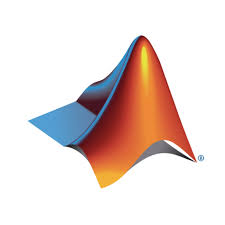

- [hyperlinks](http://www.oth-regensburg.de) 

- equations: $\sqrt {x^2}$

- tables 

interactive controls (slow with graphics)

a=30;
solution = sqrt(a)

solution = 5.4772

color picker

[0.851 0.325 0.098]

ans =     0.8510    0.3250    0.0980


#### symbolic numbers and variables

clear,clc
% symbolic numbers
x=2/3

x = 0.6667

xs=sym(2/3)

$$xs = \frac{2}{3}$$


% symbolic variables
syms a b x      % define symbolic variable
% symbolic expression
f = (x^2-a)/(x+b)

$$f = -\frac{a-x^{2}}{b+x}$$

substitute variables in expressions

b0=10;
f1 = subs(f,[a b],[sin(x) b0])

$$f1 = -\frac{\sin\left(x\right)-x^{2}}{x+10}$$


subs(f,b,[1,2,3])

$$ans = \left(\begin{array}{ccc} -\frac{a-x^{2}}{x+1} & -\frac{a-x^{2}}{x+2} & -\frac{a-x^{2}}{x+3} \end{array}\right)$$

plot symbolic function

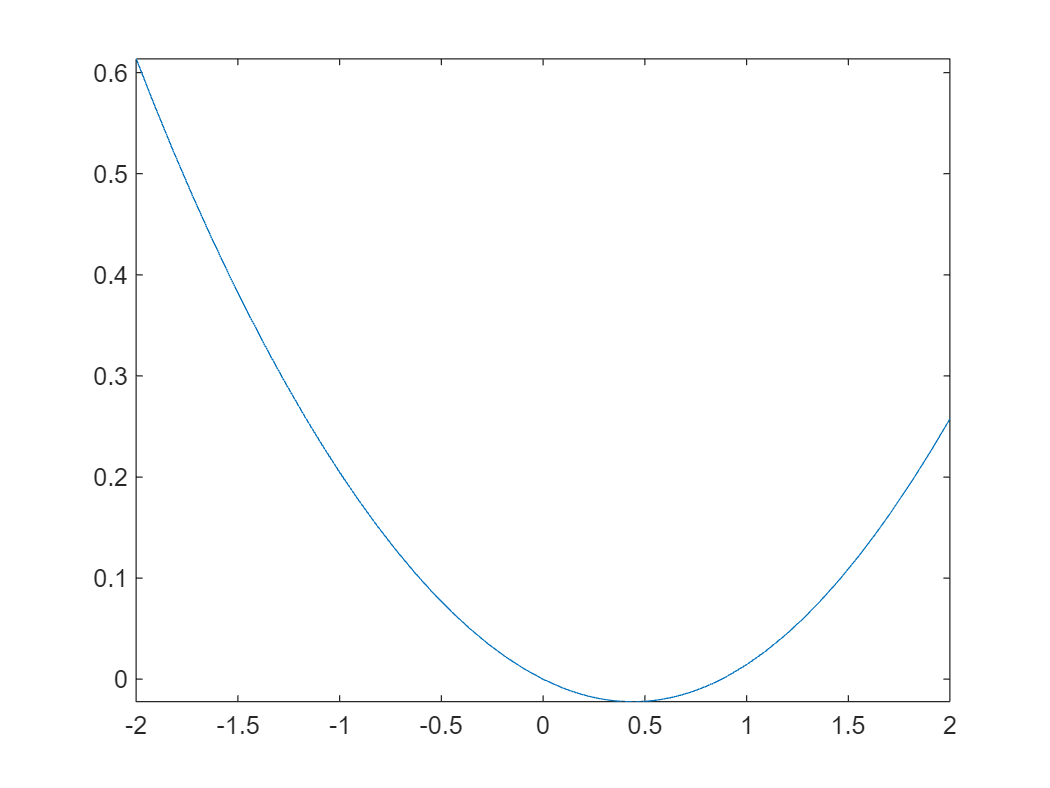

clf
fplot(f1,[-2,2])

**solve symbolic equations**

eqn = x/3 + 7 ==3;
xsol = solve(eqn,x)

$$xsol = -12$$

**systems of equations**

eqn1 = a*b==12;
eqn2 = a+b==7;
[asol,bsol] = solve([eqn1,eqn2],[a,b])

$$asol = \left(\begin{array}{c} 4\\ 3 \end{array}\right)$$

$$bsol = \left(\begin{array}{c} 3\\ 4 \end{array}\right)$$

**manipulation and simplification**

syms x
y = x*(x+2)^2 - 4*x

$$y = x\,{\left(x+2\right)}^{2}-4\,x$$

expand(y)

$$ans = x^{3}+4\,x^{2}$$

simplify(y)

$$ans = x^{2}\,\left(x+4\right)$$

factor(y)

$$ans = \left(\begin{array}{ccc} x & x & x+4 \end{array}\right)$$

example: Rotation matrix

G = [ cos(x) sin(x); -sin(x) cos(x)]; 
% two rotations in a row
G*G     

$$ans = \left(\begin{array}{cc} {\cos\left(x\right)}^{2}-{\sin\left(x\right)}^{2} & 2\,\cos\left(x\right)\,\sin\left(x\right)\\ -2\,\cos\left(x\right)\,\sin\left(x\right) & {\cos\left(x\right)}^{2}-{\sin\left(x\right)}^{2} \end{array}\right)$$

simplify(G*G)  

$$ans = \left(\begin{array}{cc} \cos\left(2\,x\right) & \sin\left(2\,x\right)\\ -\sin\left(2\,x\right) & \cos\left(2\,x\right) \end{array}\right)$$

Rewrite expression in terms of another function

clc
rewrite(sin(2*x),'tan')

$$ans = \frac{2\,\tan\left(x\right)}{{\tan\left(x\right)}^{2}+1}$$

rewrite(cos(x),'sin')

$$ans = 1-2\,{\sin\left(\frac{x}{2}\right)}^{2}$$

**assumptions**: real, integer, positive

% syms x positive
solve(x^4-1==0,x)

$$ans = \left(\begin{array}{c} -1\\ 1\\ -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

assume(x>0)
solve(x^4-1==0,x)

$$ans = 1$$

% check assumptions
assumptions

$$ans = \left(\begin{array}{ccccccc} x_{1}\in \mathbb{R} & x_{2}\in \mathbb{R} & y_{1}\in \mathbb{R} & y_{2}\in \mathbb{R} & z_{1}\in \mathbb{R} & z_{2}\in \mathbb{R} & 0<x \end{array}\right)$$

syms a b
pyth = a^2 + b^2 == 13^2

$$pyth = a^{2}+b^{2}=169$$

assume([a b],'integer')
[aInt,bInt] = solve(pyth,[a b])

$$aInt = \left(\begin{array}{c} -13\\ 0\\ 0\\ 13\\ -12\\ -12\\ -5\\ -5\\ 5\\ 5\\ 12\\ 12 \end{array}\right)$$

$$bInt = \left(\begin{array}{c} 0\\ -13\\ 13\\ 0\\ -5\\ 5\\ -12\\ 12\\ -12\\ 12\\ -5\\ 5 \end{array}\right)$$

assumeAlso([a b],'positive')
[aPos,bPos] = solve(pyth,[a b])

$$aPos = \left(\begin{array}{c} 5\\ 12 \end{array}\right)$$

$$bPos = \left(\begin{array}{c} 12\\ 5 \end{array}\right)$$

**exercise 10c.1**

simplify the expression cos(k*pi) 

a) k is an integer number 

b) k is an even number

syms k;

f = cos(k*pi)

$$f = \cos\left(\pi \,k\right)$$

assume(k, 'integer');
simplify(f)

$$ans = {\left(-1\right)}^{k}$$

assumeAlso(mod(k, 2) == 0);
assumptions

$$ans = \left(\begin{array}{cc} k\mathrm{mod}2=0 & k\in \mathbb{Z} \end{array}\right)$$

simplify(f)

$$ans = 1$$

**symbolic functions: workspace symfun**

syms a b
fx(x) = (x^2-a)/(x+b)

$$fx(x) = -\frac{a-x^{2}}{b+x}$$

fx(7)

$$ans = -\frac{a-49}{b+7}$$

fx(1:3)

$$ans = \left(\begin{array}{ccc} -\frac{a-1}{b+1} & -\frac{a-4}{b+2} & -\frac{a-9}{b+3} \end{array}\right)$$

**plots**

syms x y z
f(x,y) = x^2 + y^2

$$f(x, y) = x^{2}+y^{2}$$

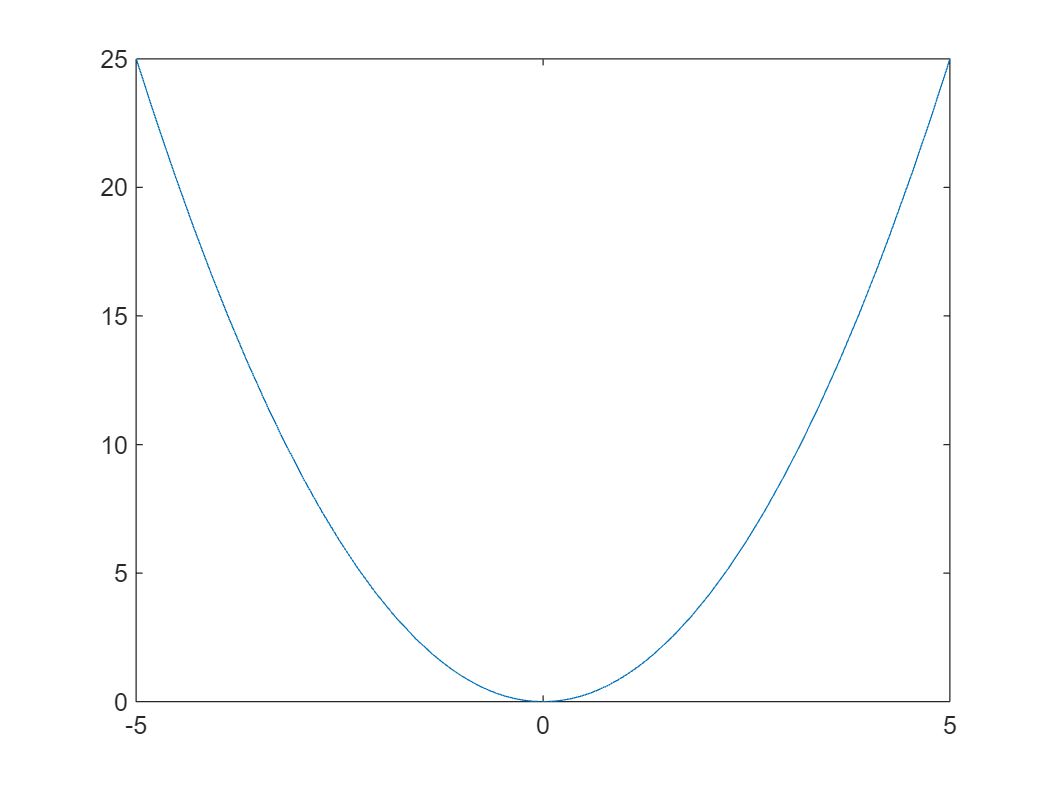

fplot(f(x,0))

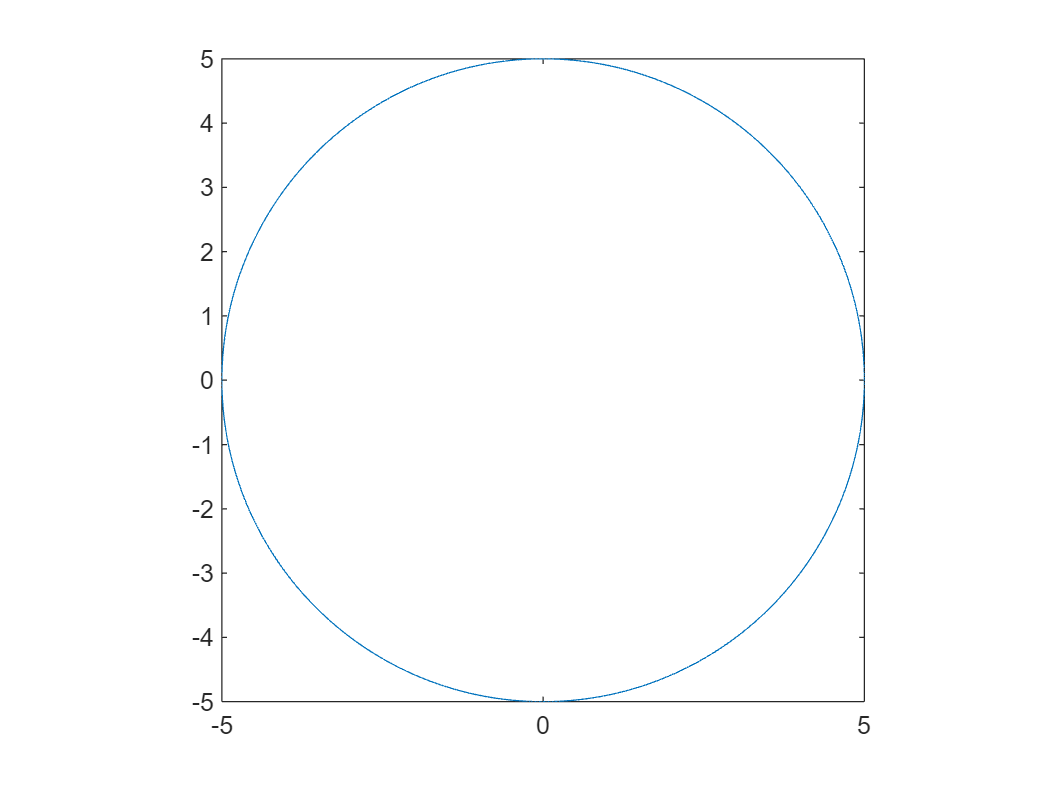

fimplicit(f == 25)
axis equal

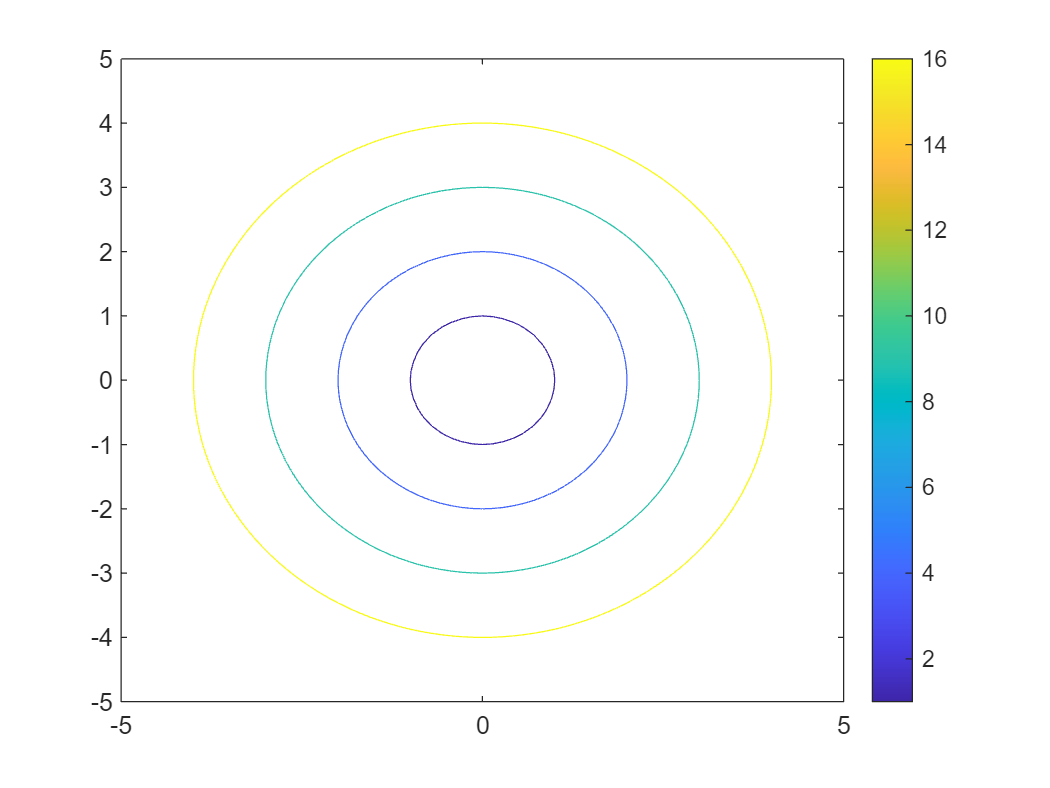

fcontour(f,'LevelList',[1 4 9 16]), colorbar

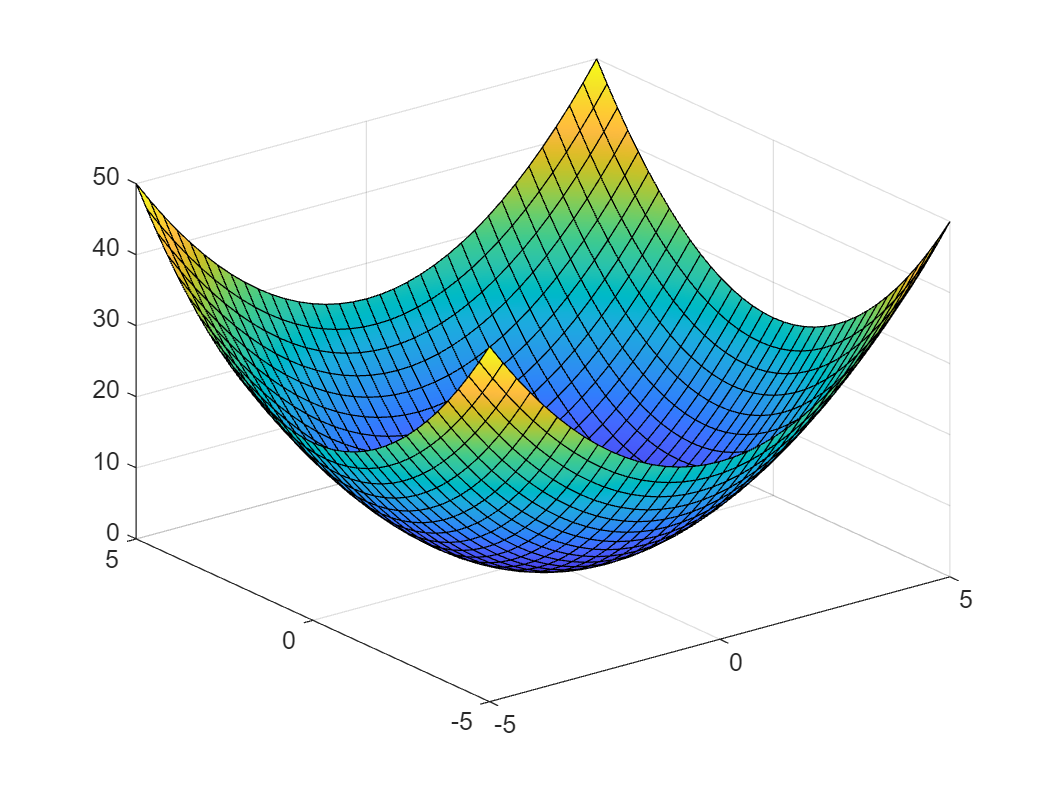

fsurf(f)

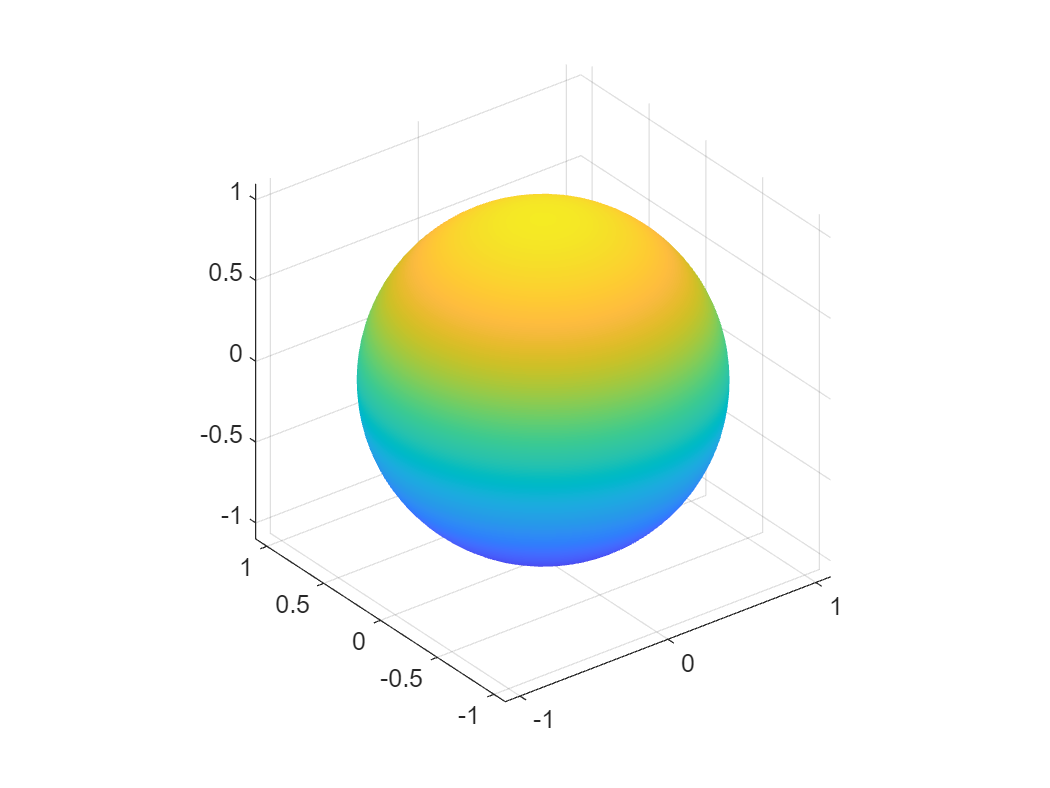

fimplicit3(x^2 + y^2 + z^2 == 1,'EdgeColor','none')
axis equal

**matrices**

syms a b c d
A=[a, b;c d];

A*A     % matrix multiplication

$$ans = \left(\begin{array}{cc} a^{2}+b\,c & a\,b+b\,d\\ a\,c+c\,d & d^{2}+b\,c \end{array}\right)$$

A.*A    % elementwise multiplication

$$ans = \left(\begin{array}{cc} a^{2} & b^{2}\\ c^{2} & d^{2} \end{array}\right)$$

inv(A)  % inverse Matrix A^-1

$$ans = \left(\begin{array}{cc} \frac{d}{a\,d-b\,c} & -\frac{b}{a\,d-b\,c}\\ -\frac{c}{a\,d-b\,c} & \frac{a}{a\,d-b\,c} \end{array}\right)$$

% distribute to multiple outputs
[a, b, c, d]=deal(1)    % a=b=c=d=1

a = 1

b = 1

c = 1

d = 1

eval(A) % evaluate symbolic matlab expression  

**sum of series**


$$\sum_{x=1}^\infty \frac{1}{x^2}$$


symsum(1./x.^2, 1, inf)

$$ans = \frac{\pi^{2}}{6}$$


$$\lim_{x \to 0} \frac{\sin x}{x}$$
 

limit(sin(x)/x,x,0)     % x->0

$$ans = 1$$

**sym2poly / poly2sym**

sym2poly(3*x^4-1)
poly2sym([1 0 0 1])

$$ans = x^{3}+1$$

**dot and cross product**

syms x1 y1 z1 x2 y2 z2 real
a=[x1 y1 z1];
b=[x2 y2 z2];
dot(a,b)    % Skalarprodukt

$$ans = x_{1}\,x_{2}+y_{1}\,y_{2}+z_{1}\,z_{2}$$

cross(a,b)  % Vektorprodukt       

$$ans = \left(\begin{array}{ccc} y_{1}\,z_{2}-y_{2}\,z_{1} & x_{2}\,z_{1}-x_{1}\,z_{2} & x_{1}\,y_{2}-x_{2}\,y_{1} \end{array}\right)$$

**taylor expansion**

taylor(sin(x),x,'ExpansionPoint', 0)

$$ans = \frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

**Differentiate symbolic expression**

syms x;
diff( sin(x)^2, x)

$$ans = 2\,\cos\left(x\right)\,\sin\left(x\right)$$

diff( (x-1)^3, x,2)      % höhere Ableitung

$$ans = 6\,x-6$$

**Indefinite integrals**

syms x t
int(x/(1 + t^2), t)

$$ans = x\,\mathrm{atan}\left(t\right)$$

**Definite integrals**

% mean of sin(x)^2
int(sin(x)^2, x, 0, 2*pi)/2/pi

$$ans = \frac{1}{2}$$

**laplace transform**

syms a  t
laplace(sin(a*t))

$$ans = \frac{a}{a^{2}+s^{2}}$$

**inverse laplace transform**

ilaplace(ans)

$$ans = \sin\left(a\,t\right)$$

**symbolic **$\rightarrow$ **anonymous function**

syms x y
r = sqrt(x^2 + y^2);
ht = matlabFunction(sin(r)/r)

ht = function_handle with value:
    @(x,y)sin(sqrt(x.^2+y.^2)).*1.0./sqrt(x.^2+y.^2)


**variable precision arithmetics**

digits(99)
vpa(pi)

$$ans = 3.14159265358979323846264338327950288419716939937510582097494459230781640628620899862803482534211707$$

digits(8)


%% create latex code
% can be used in pptx (with IguanaTex Addin) 
% % or in ELO $$-\frac{b-\sqrt{b^2-4\,a\,c}}{2\,a} $$
syms a b c
x=(-b+sqrt(b^2-4*a*c))/2/a;
latex(x);

#### **Units**

u = symunit

u =   symbolicUnitsCollection with units:

      ampere: [A]
      kelvin: [K]
    kilogram: [kg]
       meter: [m]
        mole: [mol]
      second: [s]
     candela: [cd]

  Show all units.


d = 168*u.mile

$$d = 168\,\mathrm{mi}$$

t = 4*u.hour

$$t = 4\,h$$

v = d/t

$$v = 42\,\frac{\mathrm{mi}}{h}$$

vSI=unitConvert(v,'SI')

$$vSI = \frac{58674}{3125}\,\frac{m}{s}$$

vkmh = unitConvert(v,u.km/u.hour)

$$vkmh = \frac{1056132}{15625}\,\frac{\mathrm{km}}{h}$$

[val,un] = separateUnits(vkmh)

$$val = \frac{1056132}{15625}$$

$$un = \frac{\mathrm{km}}{h}$$

% more commands
% help symbolic